# **PID CONTROLLER DESIGN AND ANALYSIS**

# **ASSIGNMENT 2**

## **PROBLEM 1:**

#### a) Open-loop Analysis:

• Plot the step response of the open-loop system

• Calculate and report: rise time, settling time, peak overshoot, and steady-state error

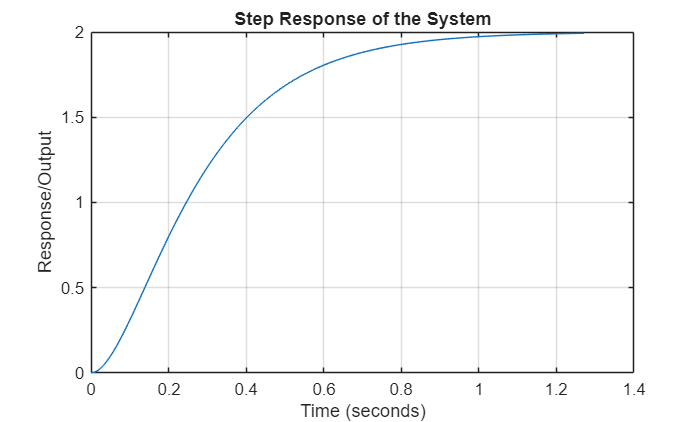

G=tf([100],[1 15 50]);
[y, t] = step(G);
plot(t, y);
title('Step Response of the System');
xlabel('Time (seconds)');
ylabel('Response/Output');
grid on;

info = stepinfo(G);
fprintf('Risetime:%.3f s\n', info.RiseTime);

Risetime:0.518 s


fprintf('Settling time: %.3f s\n', info.SettlingTime);

Settling time: 0.920 s


fprintf('Overshoot: %.2f%%\n', info.Overshoot);

Overshoot: 0.00%


fprintf('Peak:%.3f\n', info.Peak);

Peak:1.998


y_ss = y(end);
ess = 1 - y_ss; %%Unit Step

fprintf('SteadyState Error: %.3f\n', ess);

SteadyState Error: -0.993


#### b) P Controller Design:

• Design a proportional controller with Kp = 0.5 

• Plot the closed-loop step response 

• Report the performance metrics and steady-state error 

• Explain why steady-state error exists with only P control

C = pid(0.5,0,0);

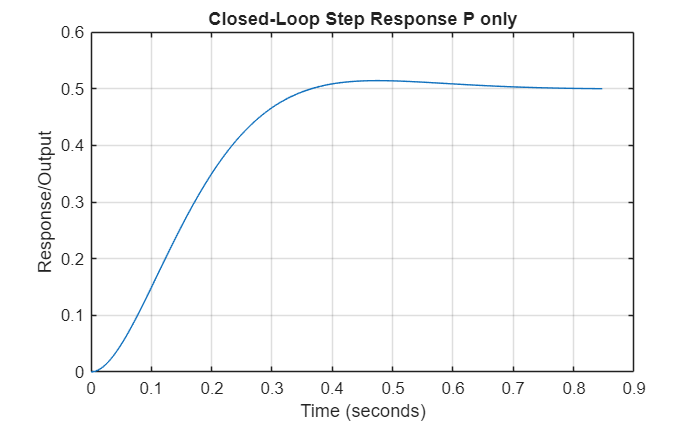

T= feedback(G*C, 1);
[y_closed, t_closed] = step(T);
plot(t_closed, y_closed);
title('Closed-Loop Step Response P only');
xlabel('Time (seconds)');
ylabel('Response/Output');
grid on;

info_closed = stepinfo(T);
fprintf('Risetime:%.3f s\n', info_closed.RiseTime);

Risetime:0.229 s


fprintf('Settling time: %.3f s\n', info_closed.SettlingTime);

Settling time: 0.574 s


fprintf('Overshoot: %.2f%%\n', info_closed.Overshoot);

Overshoot: 2.84%


fprintf('Peak:%.3f\n', info_closed.Peak);

Peak:0.514


y_ss_closed = y_closed(end);
ess_closed = 1 - y_ss_closed; %%Unit Step

fprintf('SteadyState Error: %.3f\n', ess_closed);

SteadyState Error: 0.500


In a unity-feedback system with only P control, a nonzero steady‑state error exists because the controller output is proportional to the error, so some error must remain to generate the control effort needed to balance the load and plant dynamics.

Physically,to hold a nonzero speed or position, the plant typically needs a constant input torque/voltage to balance friction and load, which the P controller provides as u=Kpe. And even the football field or drone example from the video resources.

####  c) PI Controller Design:

• Add integral action with Kp = 0.5, Ki = 1.5 

• Plot the step response and compare with P-only control 

• Report performance metrics 

• Discuss how integral action eliminated steady-state error

Ci = pid(0.5, 1.5, 0);

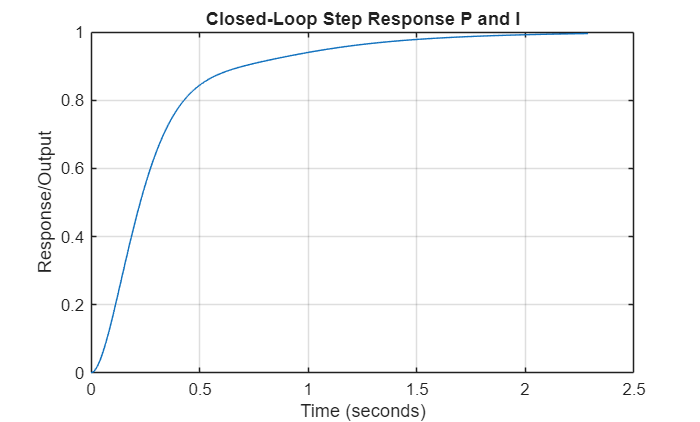

Ti= feedback(G*Ci, 1);
[y_closedi, t_closedi] = step(Ti);
plot(t_closedi, y_closedi);
title('Closed-Loop Step Response P and I');
xlabel('Time (seconds)');
ylabel('Response/Output');
grid on;

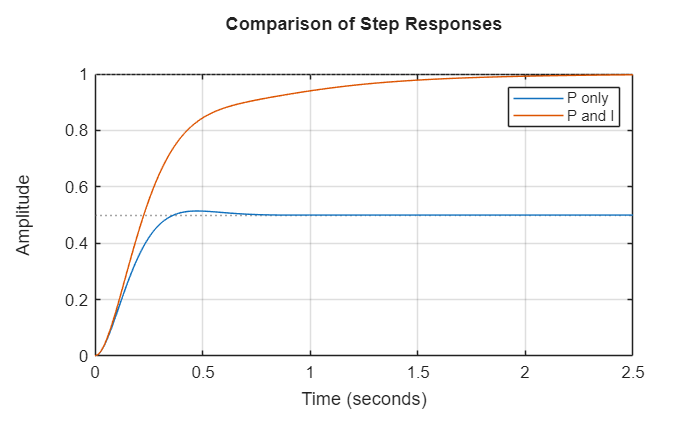

step(T, Ti);
grid on;
legend('P only', 'P and I');
title('Comparison of Step Responses');

info_closedi = stepinfo(Ti);
fprintf('Risetime:%.3f s\n', info_closedi.RiseTime);

Risetime:0.628 s


fprintf('Settling time: %.3f s\n', info_closedi.SettlingTime);

Settling time: 1.538 s


fprintf('Overshoot: %.2f%%\n', info_closedi.Overshoot);

Overshoot: 0.00%


fprintf('Peak:%.3f\n', info_closedi.Peak);

Peak:0.998


y_ss_closedi = y_closedi(end);
ess_closedi = 1 - y_ss_closedi; %%Unit Step
fprintf('SteadyState Error: %.3f\n', ess_closedi);

SteadyState Error: 0.004


Adding integral action makes the closed‑loop a TYPE-1 system, so for a step input the steady‑state error is driven essentially to zero because the integrator keeps changing the control signal as long as any error remains.

#### d) PID Controller Tuning:

• Tune the complete PID controller to achieve:

– Overshoot < 10%

– Settling time < 2 seconds

– Zero steady-state error 

• Report your final Kp, Ki, Kd values 

• Plot the final response with all metrics labeled

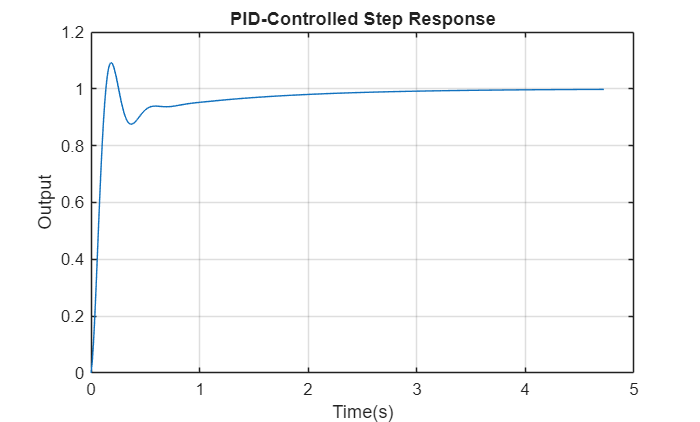

S = pidtune(G,'PID');
Kp = 3.0;
Ki = 2.99;
Kd = 0.02;
B= pid(Kp, Ki, Kd);
A = feedback(B*G, 1);

[y_pid, t_pid] = step(A);
plot(t_pid, y_pid);
grid on;
title('PID-Controlled Step Response');
xlabel('Time(s)');
ylabel('Output');


info_pid = stepinfo(A);
fprintf('Risetime:%.3f s\n', info_pid.RiseTime);

Risetime:0.095 s


fprintf('Settling time: %.3f s\n', info_pid.SettlingTime);

Settling time: 1.975 s


fprintf('Overshoot: %.2f%%\n', info_pid.Overshoot);

Overshoot: 9.25%


fprintf('Peak:%.3f\n', info_pid.Peak);

Peak:1.092


y_ss_closedpid = y_pid(end);
ess_closedpid = 1 - y_ss_closedpid; %%Unit Step
fprintf('SteadyState Error: %.3f\n', ess_closedpid);

SteadyState Error: 0.002
